clear; clc; close all;

split_percent = 28/31;
split_idx = split_percent * size(features, 2);
X_Train = features(:, 1:split_idx);
Y_Train = labels(:, 1:split_idx);
X_Test = features(:, split_idx+1:end);
Y_Test = labels(:, split_idx+1:end);

dsTrain = MyDataStore(X_Train, Y_Train);
dsTest = MyDataStore(X_Test, Y_Test);
dsTrain, dsTest

dsTrain =   MyDataStore with properties:

    Features: [25×2800000 double]
      Labels: [19×2800000 double]


dsTest =   MyDataStore with properties:

    Features: [25×300000 double]
      Labels: [19×300000 double]


layers = [
    featureInputLayer(M*M, "Normalization", "none")
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(150)
    reluLayer
    fullyConnectedLayer(2*N-1)
    regressionLayer
    ]

layers =   11×1 Layer array with layers:

     1   ''   Feature Input       25 features
     2   ''   Fully Connected     150 fully connected layer
     3   ''   ReLU                ReLU
     4   ''   Fully Connected     150 fully connected layer
     5   ''   ReLU                ReLU
     6   ''   Fully Connected     150 fully connected layer
     7   ''   ReLU                ReLU
     8   ''   Fully Connected     150 fully connected layer
     9   ''   ReLU                ReLU
    10   ''   Fully Connected     19 fully connected layer
    11   ''   Regression Output   mean-squared-error

% Compile the model with specified loss function
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 15, ...
    'MiniBatchSize', 128, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress')

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 15
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvi

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:10 |         4.84 |         11.7 |          0.0010 |
|       1 |          50 |       00:00:11 |         1.07 |          0.6 |          0.0010 |
|       1 |         100 |       00:00:12 |         0.94 |          0.4 |          0.0010 |
|       1 |         150 |       00:00:13 |         0.68 |          0.2 |          0.0010 |
|       1 |         200 |       00:00:13 |         0.73 |          0.3 |          0.0010 |
|       1 |         250 |       00:00:14 |         0.43 |      9.1e-02 |          0.0010 |
|       1 |         300 |       00:00:15 |         0.55 |         

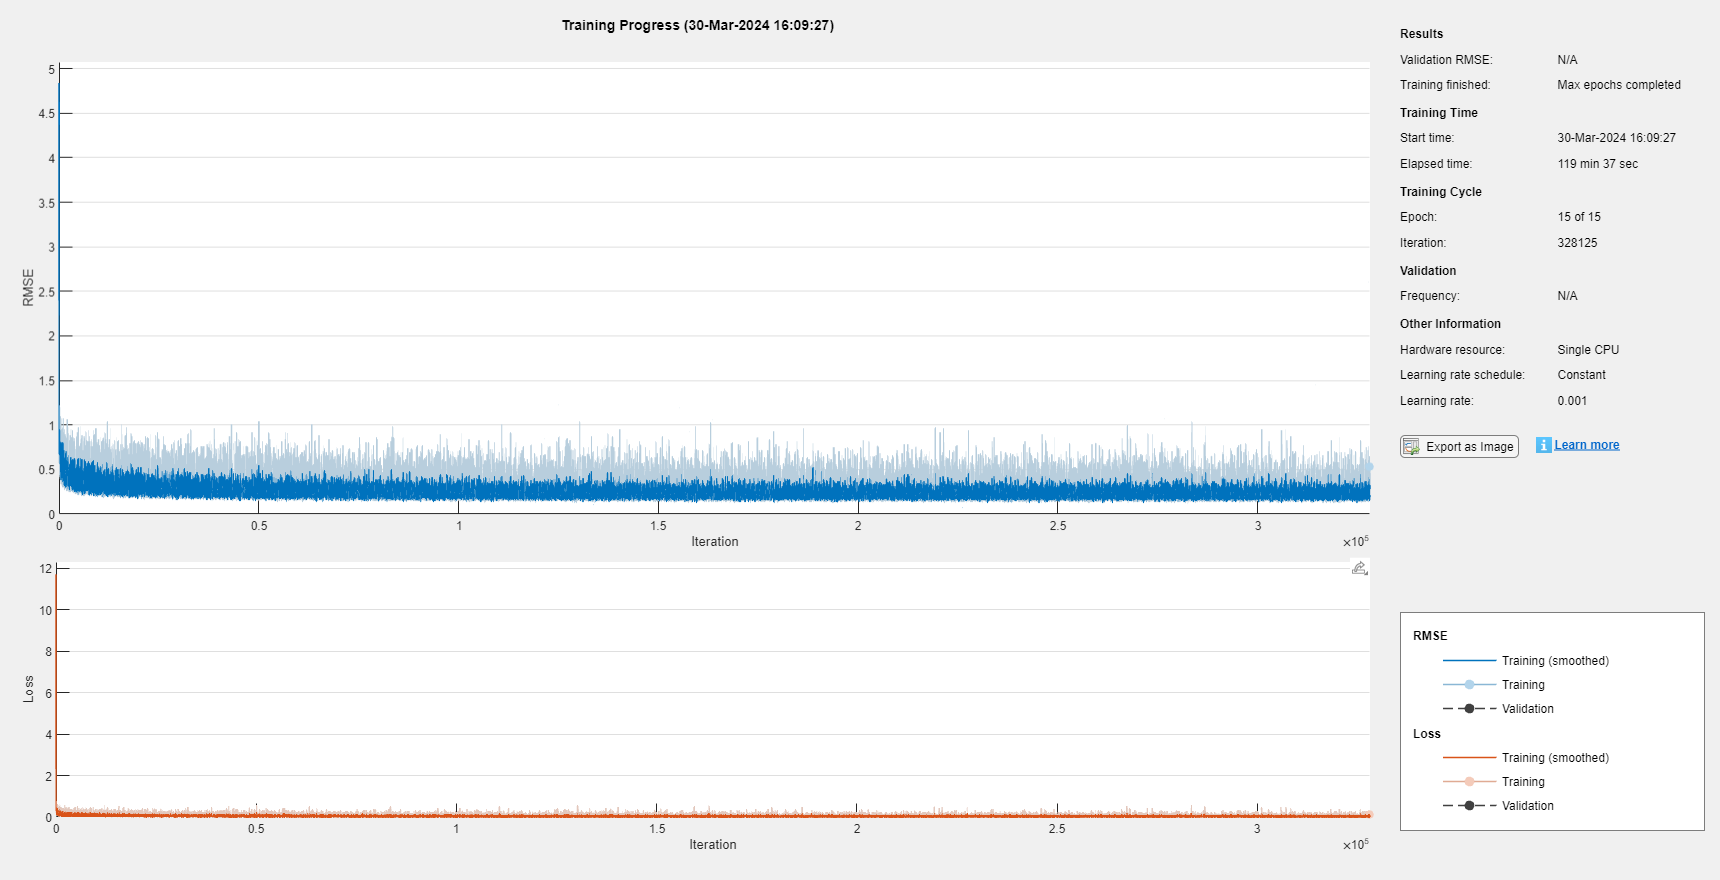

net =   SeriesNetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'regressionoutput'}


net = trainNetwork(dsTrain, layers, options)

YPred = predict(net, X_Test.').';
E = size(X_Test, 2);
avg_rmse = 0;
for i = 1:E
    avg_rmse = avg_rmse + rmse(YPred(:, i), Y_Test(:, i));
end
avg_rmse = avg_rmse / E

avg_rmse = single
0.0425

# Testing

load CRN2
addpath('D:\D\Alp\Master ODTÜ\Thesis\DOA\Codes\Direction-of-Arrival');
DOA = FunctionsOfDOA();

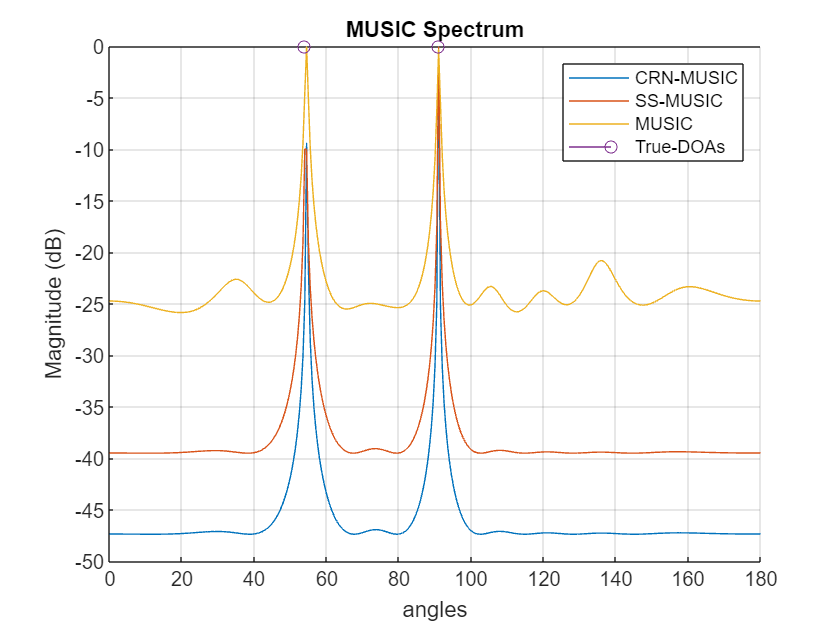

actual doa angles = 54.2069 90.9902


Test2(DOA, net);

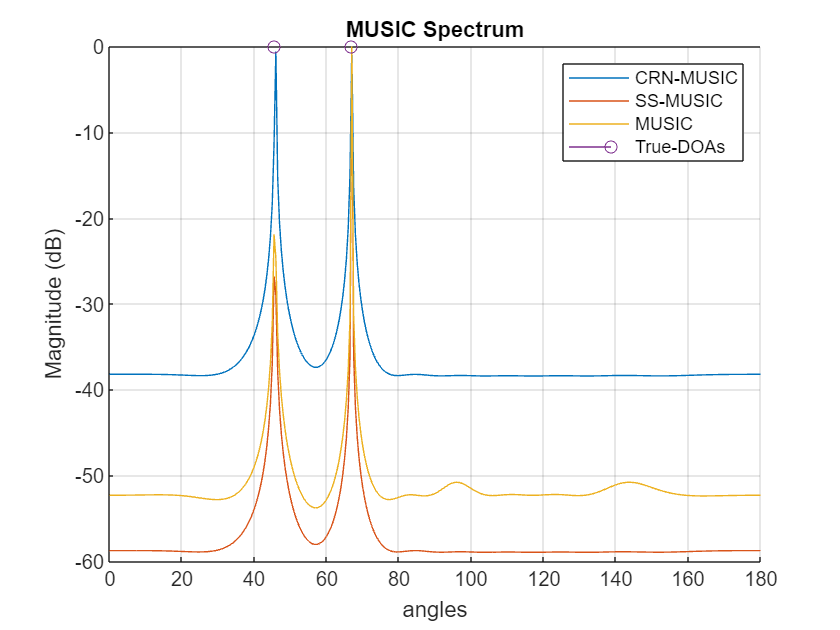

actual doa angles = 45.71 67.0164


Test2(DOA, net);

function r = R2r(R)
M = size(R, 1);
r = zeros(M*M, 1);

re_R = real(R);
im_R = imag(R);

r(1:M) = diag(re_R);
ind = M + 1;
for i = 2:M
    for j = 1:i-1
        r(ind:ind+1) = [re_R(i, j); im_R(i, j)];
        ind = ind + 2;
    end
end
end

function Test(DOA, net)
sensor_locations = [1 2 5 8 10] - 1; % SLA with 5 sensors
M = length(sensor_locations);
N = sensor_locations(M) + 1;

feature = zeros(M*M, 1);

K = 2;
L = 100;
delta_phi = 1;
phi_min = 30;
phi_max = 150;
doa = (-2 * delta_phi) * ones(1, K);
i = 1;
while true
    temp_angle = phi_min + rand * (phi_max - phi_min);
    temp_array = abs(doa - temp_angle);
    if any(temp_array < delta_phi)
        i = i - 1;
    else
        doa(i) = temp_angle;
    end
    if i == K
        break
    end
    i = i + 1;
end
doa = sort(doa);

A_ohm = DOA.Array_Manifold(0.5, sensor_locations, doa);
s = DOA.Source_Generate(K, L);
SNR_dB = 0 + rand * 30;
n = DOA.Noise_Generate(SNR_dB, M, L);
y = A_ohm * s + n;
R_ohm = (1 / L) * (y * y');

re_R = real(R_ohm);
im_R = imag(R_ohm);

feature(1:M) = diag(re_R);
ind = M + 1;
for i = 2:M
    for j = 1:i-1
        feature(ind:ind+1) = [re_R(i, j); im_R(i, j)];
        ind = ind + 2;
    end
end

label = predict(net, feature.').';
label = [label(1:N); 0; label(N+1:end)];
column_1 = label(1:N) + 1i * label(N+1:end);
R = toeplitz(column_1).';

[spectrum, angles] = DOA.MUSIC(K, 0.5, R);
figure;
plot(angles, 10*log10(spectrum));
title('MUSIC Spectrum');
ylabel('Magnitude (dB)');
xlabel('angles');
grid on;

msg = "actual doa angles =";
for i = 1:K
    msg = msg + " " + doa(i);
end
disp(msg);
end

function Test2(DOA, net)
sensor_locations = [1 2 5 8 10] - 1; % SLA with 5 sensors
M = length(sensor_locations);
N = sensor_locations(M) + 1;

feature = zeros(M*M, 1);

K = 2;
L = 100;
delta_phi = 1;
phi_min = 30;
phi_max = 150;
doa = (-2 * delta_phi) * ones(1, K);
i = 1;
while true
    temp_angle = phi_min + rand * (phi_max - phi_min);
    temp_array = abs(doa - temp_angle);
    if any(temp_array < delta_phi)
        i = i - 1;
    else
        doa(i) = temp_angle;
    end
    if i == K
        break
    end
    i = i + 1;
end
doa = sort(doa);

A_ohm = DOA.Array_Manifold(0.5, sensor_locations, doa);
s = DOA.Source_Generate(K, L);
SNR_dB = 0 + rand * 30;
n = DOA.Noise_Generate(SNR_dB, M, L);
y = A_ohm * s + n;
R_ohm = (1 / L) * (y * y');

re_R = real(R_ohm);
im_R = imag(R_ohm);

feature(1:M) = diag(re_R);
ind = M + 1;
for i = 2:M
    for j = 1:i-1
        feature(ind:ind+1) = [re_R(i, j); im_R(i, j)];
        ind = ind + 2;
    end
end

label = predict(net, feature.').';
label = [label(1:N); 0; label(N+1:end)];
column_1 = label(1:N) + 1i * label(N+1:end);
R = toeplitz(column_1).';

figure; hold on;

z = R_ohm(:);
[z1, M_v] = DOA.Rearrange_According_to_Sensor_Locations(z, sensor_locations);
R_z1 = zeros(M_v);
for i = 1:M_v
    z1_i = z1(i:i + M_v - 1);
    R_z1 = R_z1 + (1 / M_v) * (z1_i * z1_i');
end

cov_mat = {R, R_z1, R_ohm};
sensor_locs = {0:N-1, 0:N-1, sensor_locations};
for i = 1:length(cov_mat)
    [spectrum, angles] = DOA.MUSIC(K, 0.5, cov_mat{i}, sensor_locs{i});
    plot(angles, 10*log10(spectrum));
end

rounded_doa = round(doa * 2) / 2;
stem(rounded_doa, zeros(1, K));

title('MUSIC Spectrum');
ylabel('Magnitude (dB)');
xlabel('angles');
grid on;
legend('CRN-MUSIC', 'SS-MUSIC', 'MUSIC', 'True-DOAs')

msg = "actual doa angles =";
for i = 1:K
    msg = msg + " " + doa(i);
end
disp(msg);
end